# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);

- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

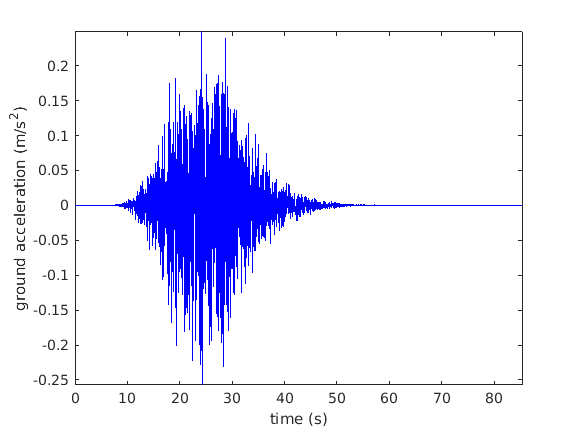

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

Earthquake data has been generated.

### Single-level 1-D discrete wavelet transform;

`[`[`cA`](https://in.mathworks.com/help/wavelet/ref/dwt.html#d122e21583)`,`[`cD`](https://in.mathworks.com/help/wavelet/ref/dwt.html#d122e21631)`] = dwt(`[`x`](https://in.mathworks.com/help/wavelet/ref/dwt.html#d122e21333)`,`[`wname`](https://in.mathworks.com/help/wavelet/ref/dwt.html#d122e21374)`)` returns the single-level discrete wavelet transform (DWT) of the vector `x` using the wavelet specified by `wname`. The wavelet must be recognized by [`wavemngr`](https://in.mathworks.com/help/wavelet/ref/wavemngr.html). `dwt` returns the approximation coefficients vector `cA` and detail coefficients vector `cD` of the DWT.

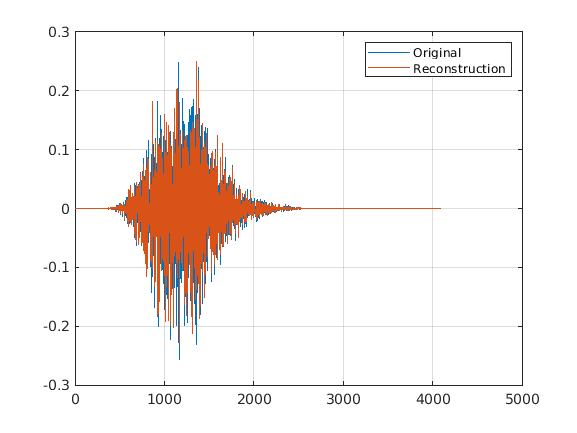

[cA,cD] = dwt(y,'sym4');
xrec = idwt(cA,zeros(size(cA)),'sym4');
plot(y)
hold on
grid on
plot(xrec)
legend('Original','Reconstruction')

### **DWT Using Wavelet and Scaling Filters**

Obtain the single-level DWT of a  signal using the wavelet (highpass) and scaling (lowpass) filters.

[LoD,HiD] = wfilters('bior3.5','d');
[cA,cD] = dwt(y,LoD,HiD);

Create a DWT filter bank that can be applied to the noisy Doppler signal using the same wavelet. Obtain the highpass and lowpass filters from the filter bank

len = length(y);
fb = dwtfilterbank('SignalLength',len,'Wavelet','bior3.5');
[lo,hi] = filters(fb);

For the `bior3.5` wavelet, `lo` and `hi` are 12-by-2 matrices. `lo` are the lowpass filters, and `hi` are the highpass filters. The first columns of `lo` and `hi` are used for analysis and the second columns are used for synthesis. Compare the first column of `lo` and `hi` with `LoD` and `HiD` respectively. Confirm they are equal.

disp('Lowpass Analysis Filters')

Lowpass Analysis Filters


[lo(:,1) LoD']

ans =    -0.0138   -0.0138
    0.0414    0.0414
    0.0525    0.0525
   -0.2679   -0.2679
   -0.0718   -0.0718
    0.9667    0.9667
    0.9667    0.9667
   -0.0718   -0.0718
   -0.2679   -0.2679
    0.0525    0.0525


disp('Highpass Analysis Filters')

Highpass Analysis Filters


[hi(:,1) HiD']

ans =          0         0
         0         0
         0         0
         0         0
   -0.1768   -0.1768
    0.5303    0.5303
   -0.5303   -0.5303
    0.1768    0.1768
         0         0
         0         0


Plot the one-sided magnitude frequency responses of the first-level wavelet and scaling filters.

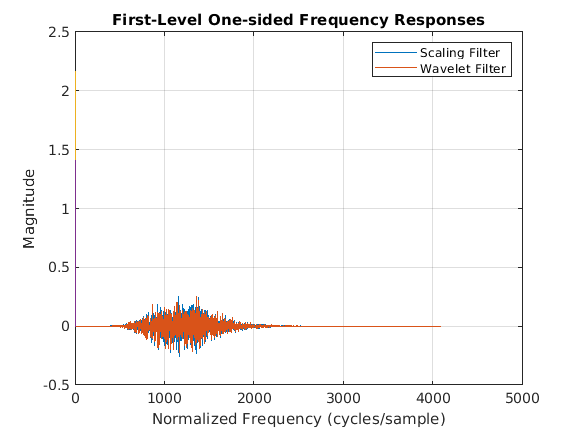

[psidft,f,phidft] = freqz(fb);
level = 1;
plot(f(len/2+1:end),abs(phidft(level,len/2+1:end)))
hold on
plot(f(len/2+1:end),abs(psidft(level,len/2+1:end)))
grid on
legend('Scaling Filter','Wavelet Filter')
title('First-Level One-sided Frequency Responses')
xlabel('Normalized Frequency (cycles/sample)')
ylabel('Magnitude')

### Wavelet Analysis of the Data:

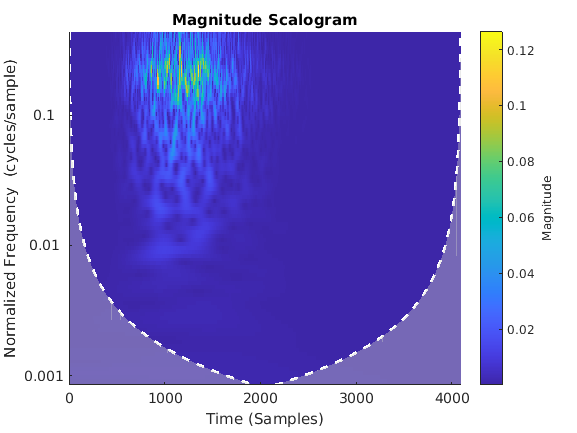

cwt(y)

### **Detecting Discontinuities and Breakdown Points if present**

Signals with very rapid evolutions such as transient signals in dynamic systems may undergo abrupt changes such as a jump, or a sharp change in the first or second derivative. Fourier analysis is usually not able to detect those events. The purpose of this example is to show how analysis by wavelets can detect the exact instant when a signal changes and also the type (a rupture of the signal, or an abrupt change in its first or second derivative) and amplitude of the change.

Compute the multilevel 1-D wavelet decomposition at level 1.

level = 1;
[c,l] = wavedec(y,level,'haar');

Extract the detail coefficients at level 1 from the wavelet decomposition and visualize the result. Interpolate the detail coefficients so they and the signal have the same length.

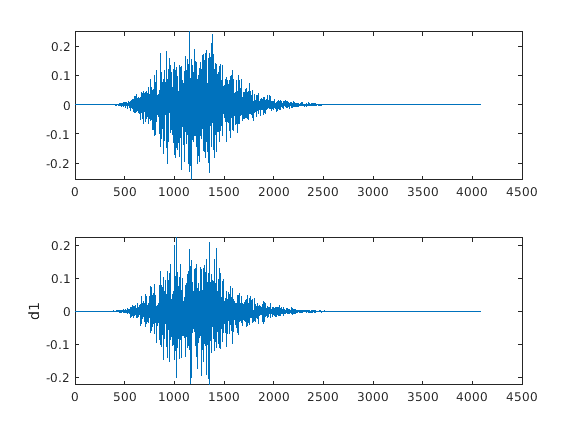

d1 = detcoef(c,l,level);
subplot(2,1,1)
plot(y)
subplot(2,1,2)
plot(interpft(d1,2*length(d1)))
ylabel('d1')

The first-level details (`d1`) show the discontinuity most clearly, because the rupture contains the high-frequency part. The discontinuity is localized very precisely around time = 500.

The presence of noise makes identification of discontinuities more complicated. If the finer levels of the decomposition can be used to eliminate a large part of the noise, the rupture is sometimes visible at coarser levels in the decomposition.

**Second Derivation Breakdown**

The purpose of this example is to show how analysis by wavelets can detect a discontinuity in one of a signal's derivatives. The signal, while apparently a single smooth curve, is actually composed of two separate exponentials.

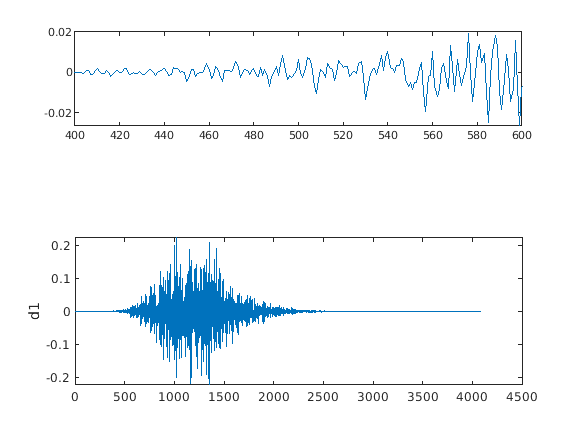

level = 2;
[c,l] = wavedec(y,level,'db4');
[d1,d2] = detcoef(c,l,1:level);
d1up = dyadup(d1,0);
d2up = dyadup(dyadup(d2,0),0);
subplot(3,1,1)
plot(y)
xlim([400 600])

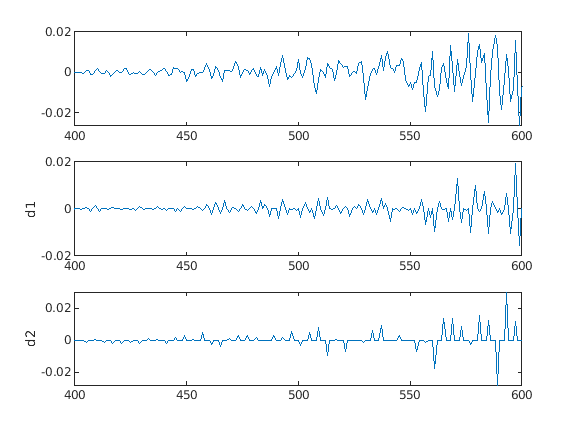

subplot(3,1,2)
plot(d1up)
ylabel('d1')
xlim([400 600])
subplot(3,1,3)
plot(d2up)
ylabel('d2')
xlim([400 600])

#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end